讀取影像

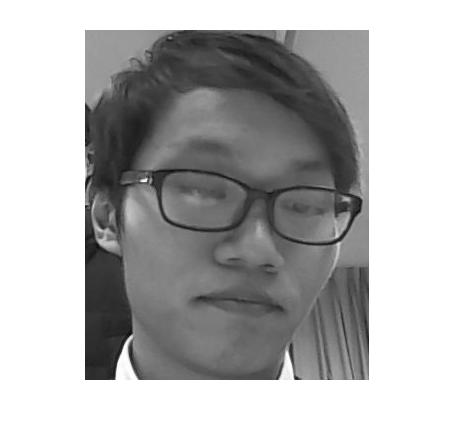

I1 = imread('Img1.jpg');
G1 = rgb2gray(I1);
 imshow(G1)

旋轉影像

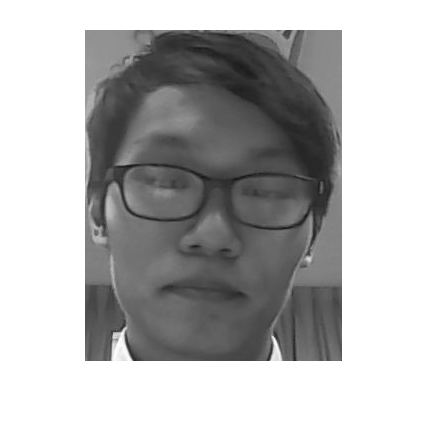

I2 = imread('Img2.jpg');%G2 = imresize(imrotate(G1,-20),1.2);
G2 = rgb2gray(I2);
imshow(G2)

尋找SURF特徵

points1 = detectSURFFeatures(G1)

Previously accessible file "D:\Documents\GitHub\Matlab\detectSURFFeatures.mlx" is now inaccessible.


points2 = detectSURFFeatures(G2)

提取特徵

[f1,vpts1] = extractFeatures(G1,points1);

f1 =     0.0003    0.0005    0.0003    0.0006    0.0379    0.0148    0.0486    0.0154   -0.0172   -0.0070    0.0442    0.0119   -0.0005    0.0005    0.0005    0.0005    0.0014   -0.0020    0.0017    0.0020    0.3536    0.0397    0.3938    0.0490   -0.2631    0.1039    0.4230    0.1991    0.0017   -0.0042    0.0051    0.0050    0.0011    0.0003    0.0015    0.0011    0.3660   -0.0030    0.3854    0.0520   -0.1814    0.1355    0.2041    0.1556   -0.0033    0.0040    0.0221    0.0210   -0.0000    0.0002
   -0.0028   -0.0011    0.0029    0.0031    0.0017   -0.0312    0.0078    0.0331   -0.0146   -0.0219    0.0312    0.0277   -0.0017   -0.0032    0.0018    0.0040   -0.0393    0.0058    0.0393    0.0299    0.3103    0.0476    0.3103    0.1215   -0.2840    0.1133    0.3600    0.1347   -0.0056    0.0096    0.0072    0.0096   -0.0551   -0.0075    0.0569    0.0600    0.2166   -0.0876    0.2623    0.2171   -0.0672   -0.0617    0.5298    0.2383   -0.0224    0.0341    0.0238    0.0341   -0.0066    

vpts1 =   65x1 SURFPoints array with properties:

              Scale: [65x1 single]
    SignOfLaplacian: [65x1 int8]
        Orientation: [65x1 single]
           Location: [65x2 single]
             Metric: [65x1 single]
              Count: 65


[f2,vpts2] = extractFeatures(G2,points2);

f2 =    -0.0000    0.0005    0.0006    0.0005    0.0041   -0.0050    0.0092    0.0064    0.0054   -0.0003    0.0215    0.0117    0.0001   -0.0000    0.0002    0.0006    0.0003    0.0023    0.0017    0.0023    0.1190    0.1849    0.1773    0.1997   -0.0092    0.1473    0.5077    0.2004   -0.0057    0.0030    0.0057    0.0054    0.0039    0.0021    0.0044    0.0023    0.2988   -0.0769    0.3668    0.1164   -0.1122    0.1819    0.4567    0.2325   -0.0147    0.0026    0.0248    0.0317    0.0005    0.0000
   -0.0014    0.0009    0.0014    0.0009   -0.0046   -0.0024    0.0225    0.0230    0.0265    0.0058    0.0468    0.0168   -0.0007    0.0035    0.0007    0.0037   -0.0104    0.0041    0.0138    0.0076    0.1487    0.1260    0.2577    0.1967    0.0369    0.1721    0.4270    0.3194   -0.0096    0.0188    0.0097    0.0188   -0.0113    0.0111    0.0156    0.0160    0.3657    0.0021    0.4531    0.0790   -0.1964    0.0960    0.2893    0.1870    0.0280   -0.0282    0.0590    0.0539    0.0006    

vpts2 =   33x1 SURFPoints array with properties:

              Scale: [33x1 single]
    SignOfLaplacian: [33x1 int8]
        Orientation: [33x1 single]
           Location: [33x2 single]
             Metric: [33x1 single]
              Count: 33


檢索匹配點的位置

indexPairs = matchFeatures(f1,f2) ;
matchedPoints1 = vpts1(indexPairs(:,1));
matchedPoints2 = vpts2(indexPairs(:,2));

顯示配對點

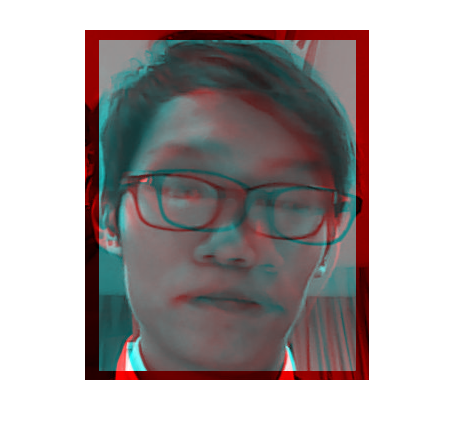

figure; showMatchedFeatures(G1,G2,matchedPoints1,matchedPoints2);

legend('matched points 1','matched points 2');